# Logistic Regression for Iris Data Set

## Load Iris data

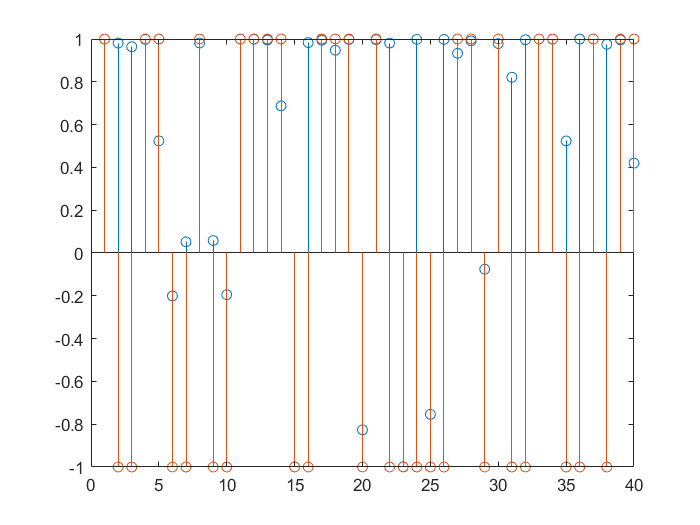

clear;
load iris_dataset
data = irisInputs;
X = data(1:2,1:100);
% data and label
X = [X;ones(1,100)];
y = [ones(1,50),-1*ones(1,50)];

% splite the training and test sets
idx = randperm(100);
X_train = X(:,idx(1:60));
y_train = y(idx(1:60));
X_test = X(:,idx(61:100));
y_test = y(idx(61:100));

% Use the gradient descent algorithm to obtain the parameter w
y_aug = repmat(y_train,3,1);
w = [1,1,1]';
alpha = 0.01;
for iter = 1:10000
    X_y = y_aug.*X_train;
    outp = my_sigd(w,X_y);
    NLL(iter) = - sum(log(outp));
    dldw = my_gradient(w,X_y);
    w = w - alpha*dldw;
end

p1 = my_sigd(w,X_test);
pred = p1*2-1;
stem(pred);
hold on
stem(y_test);

## sigmoid function

function output = my_sigd(w,x)
% the dimension of matrix x is (d+1) by n，d is the dimension of a data point，d+1 is the extended dimension；
% n is the number of the data points
% w is the paramter: [w;b]
    temp =exp(-w'*x);
    output = 1./(1+temp);
end


## gradient function for NLL of Logistic regression


$$\partial L/\partial W = -\sum_{n=1}^N\frac{y_nx_n}{1+exp(y_nW^Tx_n)}$$


function dldw =my_gradient(w,x)
    temp =exp(w'*x);
    output = 1./(1+temp).*x;  
    dldw = -sum(output,2);
end